Addpath

clear;clc;
close all
addpath("PandaDyn\")
addpath("Dynamics\")

Sampling Time, Time Step & Simulation Time

dt=2e-5;
SamplingTime=[0.002;0.0075;0.008];
SimulationTime=1.0;
TimeSpan=0:dt:SimulationTime;

Initial Condition

TargetAngle=[pi/2,pi/4,pi/6,pi/3,-pi/6,-pi/2,pi/3]';
StateInitial=[TargetAngle+0.01;zeros(7,1)];

Gains

Kp=0.1*diag([600,600,600,600,250,150,50]);
Kd=0.1*diag([50,50,50,20,20,20,10]);

Solver Option

option=odeset('RelTol', 1e-12, 'AbsTol', 1e-12);

File Name

Name=["Stable","Periodic","Diverge"];

Time History

StateTimeHistory=zeros(7*2*3,round(SimulationTime/dt)+1);
TorqueTimeHistory=zeros(7*3,round(SimulationTime/dt)+1);
TorqueTimeHistoryContinuous=zeros(7,round(SimulationTime/dt)+1);

### Continuous Time Case

Simulation

tic
[t,State]=ode45(@(t,State)ODE(t,State,PDTorque(Kp,Kd,State,TargetAngle)),TimeSpan,StateInitial,option);
StateTimeHistoryContinuous=State';
for i=1:round(SimulationTime/dt)+1
    TorqueTimeHistoryContinuous(:,i)=PDTorque(Kp,Kd,StateTimeHistoryContinuous(:,i),TargetAngle);
end
toc

历时 3.574854 秒。


### Digital Feedback Control Case

Simulation

for j=1:3
    ts=SamplingTime(j);
    % Time History Matrix
    StateTimeHistoryDigital=zeros(7*2,round(SimulationTime/dt)+1);
    SampledStateTimeHistoryDigital=zeros(7*2,floor(SimulationTime/ts));
    TorqueTimeHistoryDigital=zeros(7,round(SimulationTime/dt)+1);
    StateTimeHistoryDigital(:,1)=StateInitial;
    SampledStateTimeHistoryDigital(:,1)=StateInitial;
    TorqueTimeHistoryDigital(:,1)=PDTorque(Kp,Kd,SampledStateTimeHistoryDigital(:,1),TargetAngle);
    TorqueTimeHistoryContinuous=zeros(7,round(SimulationTime/dt)+1);
    tic
    bar=waitbar(0,"Start Simulation");
    for i=1:floor(SimulationTime/ts)
        SampledStateTimeHistoryDigital(:,i)=StateTimeHistoryDigital(:,(i-1)*round(ts/dt)+1);
        if i==1
            Tau=PDTorque(Kp,Kd,SampledStateTimeHistoryDigital(:,1),TargetAngle);
        else
            Tau=PDTorque(Kp,Kd,SampledStateTimeHistoryDigital(:,i-1),TargetAngle);
        end
        TorqueTimeHistoryDigital(:,(i-1)*round(ts/dt)+2:i*round(ts/dt)+1)=repmat(Tau,1,round(ts/dt));
        [t,State]=ode45(@(t,State)ODE(t,State,Tau),TimeSpan((i-1)*round(ts/dt)+1:i*round(ts/dt)+1),StateTimeHistoryDigital(:,(i-1)*round(ts/dt)+1),option);
        StateTimeHistoryDigital(:,(i-1)*round(ts/dt)+2:i*round(ts/dt)+1)=State(2:end,:)';
        str=[num2str(100*i/floor(SimulationTime/ts)),'%',' Finished'];
        waitbar(i/floor(SimulationTime/ts),bar,str);
    end
    waitbar(1,bar,"Handling Final Interval");
    if floor(SimulationTime/ts)~=ceil(SimulationTime/ts)
        [t,State]=ode45(@(t,State)ODE(t,State,Tau),TimeSpan(floor(SimulationTime/ts)*round(ts/dt)+1:end),StateTimeHistoryDigital(:,floor(SimulationTime/ts)*round(ts/dt)+1),option);
        StateTimeHistoryDigital(:,floor(SimulationTime/ts)*round(ts/dt)+2:end)=State(2:end,:)';
        TorqueTimeHistoryDigital(:,floor(SimulationTime/ts)*round(ts/dt)+2:end)=repmat(Tau,1,round(mod(SimulationTime,ts)/dt));
    end
    delete(bar);
    toc
    StateTimeHistory(7*2*(j-1)+1:7*2*j,:)=StateTimeHistoryDigital;
    TorqueTimeHistory(7*(j-1)+1:7*j,:)=TorqueTimeHistoryDigital;
end

历时 24.070461 秒。
历时 26.895109 秒。
历时 33.976653 秒。


MDH parameter of Franka Emika Panda

mdl_panda

Trajectory of End Effector

EndEffectorLocContinuous=panda.fkine(StateTimeHistoryContinuous(1:7,:)').transl';
EndEffectorLocDigital_1=panda.fkine(StateTimeHistory(1:7,:)').transl';
EndEffectorLocDigital_2=panda.fkine(StateTimeHistory(15:21,:)').transl';
EndEffectorLocDigital_3=panda.fkine(StateTimeHistory(29:35,:)').transl';

Target of End Effector

EndEffectorLocTarget=panda.fkine(TargetAngle).transl';

End Effector Trajectory

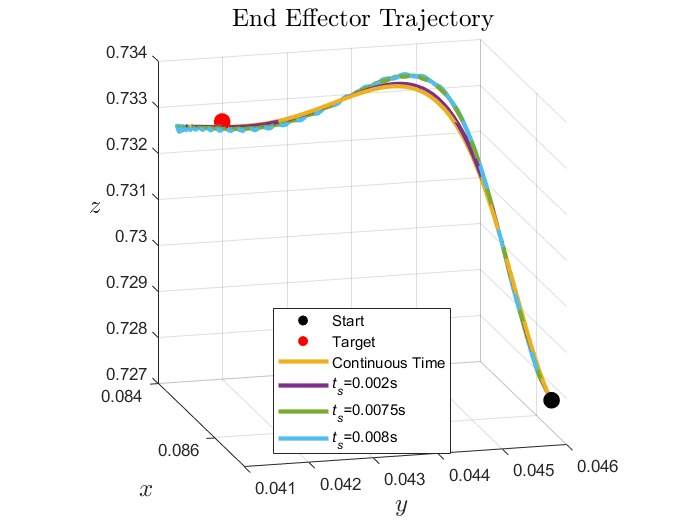

scatter3(EndEffectorLocContinuous(1,1),EndEffectorLocContinuous(2,1),EndEffectorLocContinuous(3,1),100,"black","filled","o")
hold on
scatter3(EndEffectorLocTarget(1),EndEffectorLocTarget(2),EndEffectorLocTarget(3),100,"red","filled","o")
plot3(EndEffectorLocContinuous(1,:),EndEffectorLocContinuous(2,:),EndEffectorLocContinuous(3,:),"LineWidth",2.5)
plot3(EndEffectorLocDigital_1(1,:),EndEffectorLocDigital_1(2,:),EndEffectorLocDigital_1(3,:),"LineWidth",2.5)
plot3(EndEffectorLocDigital_2(1,:),EndEffectorLocDigital_2(2,:),EndEffectorLocDigital_2(3,:),"LineWidth",2.5)
plot3(EndEffectorLocDigital_3(1,:),EndEffectorLocDigital_3(2,:),EndEffectorLocDigital_3(3,:),"LineWidth",2.5)
hold off
title("End Effector Trajectory", ...
    "FontSize",15,"Interpreter","latex")
view(75,15)
pbaspect([1 1 1])
legend("Start","Target","Continuous Time", ...
    "\itt_s=\rm"+num2str(SamplingTime(1))+"s", ...
    "\itt_s=\rm"+num2str(SamplingTime(2))+"s", ...
    "\itt_s=\rm"+num2str(SamplingTime(3))+"s","Location","south")
xlabel("$$x$$","Interpreter","latex","FontSize",15)
ylabel("$$y$$","Interpreter","latex","FontSize",15)
zlabel("$$z$$","Interpreter","latex","FontSize",15,"Rotation",pi/2)

End Effector Error Visualization

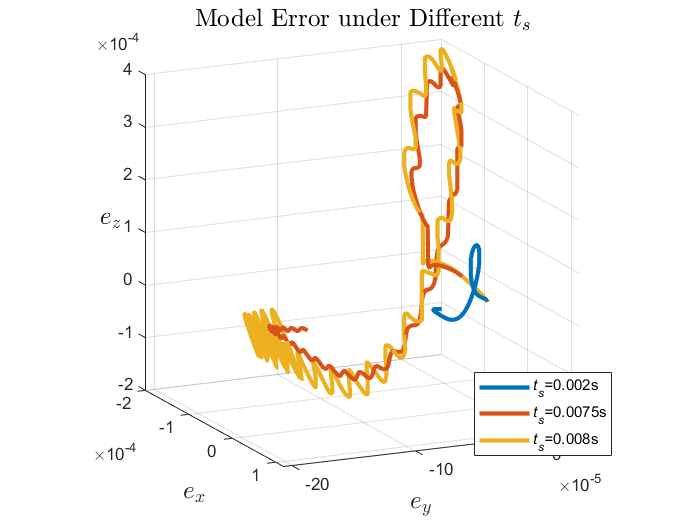

plot3(EndEffectorLocDigital_1(1,:)-EndEffectorLocContinuous(1,:), ...
    EndEffectorLocDigital_1(2,:)-EndEffectorLocContinuous(2,:), ...
    EndEffectorLocDigital_1(3,:)-EndEffectorLocContinuous(3,:),"LineWidth",2.5)
hold on
plot3(EndEffectorLocDigital_2(1,:)-EndEffectorLocContinuous(1,:), ...
    EndEffectorLocDigital_2(2,:)-EndEffectorLocContinuous(2,:), ...
    EndEffectorLocDigital_2(3,:)-EndEffectorLocContinuous(3,:),"LineWidth",2.5)
plot3(EndEffectorLocDigital_3(1,:)-EndEffectorLocContinuous(1,:), ...
    EndEffectorLocDigital_3(2,:)-EndEffectorLocContinuous(2,:), ...
    EndEffectorLocDigital_3(3,:)-EndEffectorLocContinuous(3,:),"LineWidth",2.5)
hold off
pbaspect([1 1 1])
xlabel("$$e_x$$","Interpreter","latex","FontSize",15)
ylabel("$$e_y$$","Interpreter","latex","FontSize",15)
zlabel("$$e_z$$","Interpreter","latex","FontSize",15,"Rotation",pi/2)
legend("\itt_s=\rm"+num2str(SamplingTime(1))+"s", ...
    "\itt_s=\rm"+num2str(SamplingTime(2))+"s", ...
    "\itt_s=\rm"+num2str(SamplingTime(3))+"s","Location","best")
title("Model Error under Different $$t_s$$", ...
    "FontSize",15,"Interpreter","latex")
view(65,15)
grid on

End Effector Error Time History

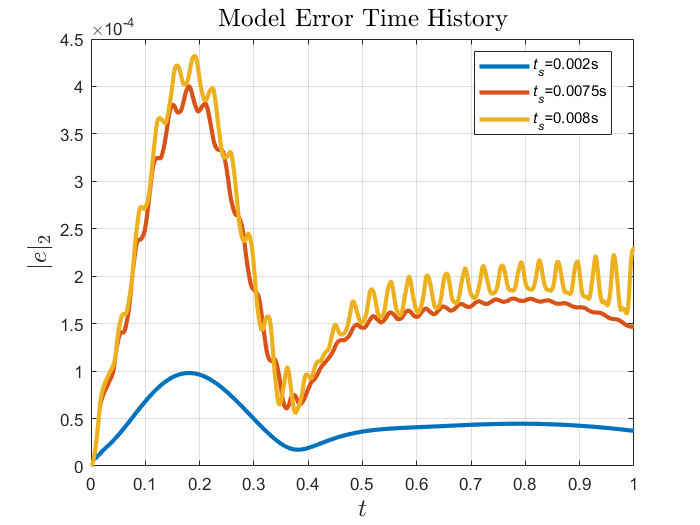

EndEffectorErrorDigital_1=zeros(size(TimeSpan));
EndEffectorErrorDigital_2=zeros(size(TimeSpan));
EndEffectorErrorDigital_3=zeros(size(TimeSpan));
for i=1:length(TimeSpan)
    EndEffectorErrorDigital_1(i)=norm(EndEffectorLocDigital_1(:,i)-EndEffectorLocContinuous(:,i));
    EndEffectorErrorDigital_2(i)=norm(EndEffectorLocDigital_2(:,i)-EndEffectorLocContinuous(:,i));
    EndEffectorErrorDigital_3(i)=norm(EndEffectorLocDigital_3(:,i)-EndEffectorLocContinuous(:,i));
end
plot(TimeSpan,EndEffectorErrorDigital_1,"LineWidth",2.5)
hold on
plot(TimeSpan,EndEffectorErrorDigital_2,"LineWidth",2.5)
plot(TimeSpan,EndEffectorErrorDigital_3,"LineWidth",2.5)
hold off
title("Model Error Time History","FontSize",15,"Interpreter","latex")
legend("\itt_s=\rm"+num2str(SamplingTime(1))+"s", ...
    "\itt_s=\rm"+num2str(SamplingTime(2))+"s", ...
    "\itt_s=\rm"+num2str(SamplingTime(3))+"s","Location","best")
xlabel("$$t$$","Interpreter","latex","FontSize",15)
ylabel("$$|e|_2$$","Interpreter","latex","FontSize",15)
grid on